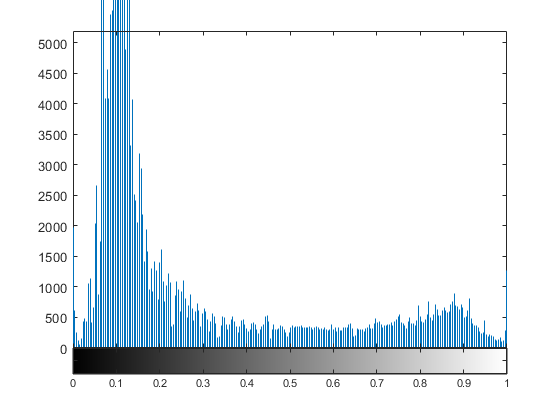

Image = imread("Einstein1.jpg");
I2 = im2double(Image);
imhist(I2)

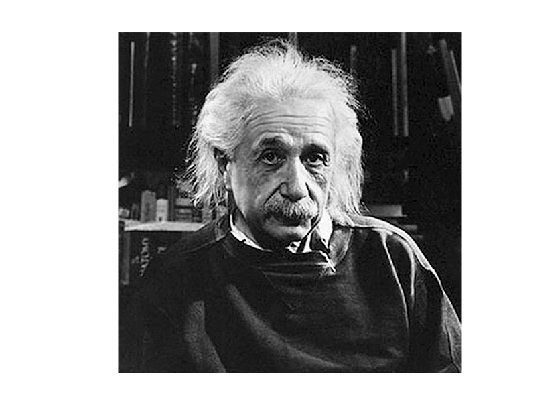

imshow(I2)

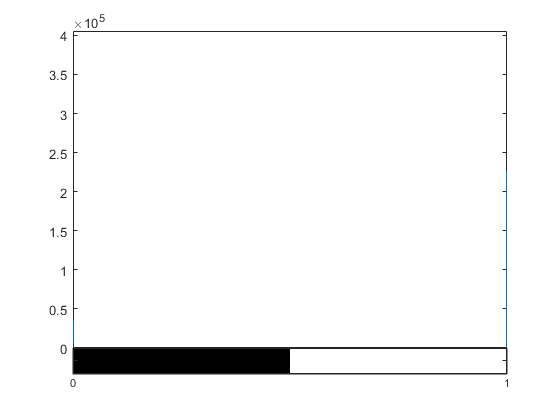

T = 0.7;
Ib = I2 < T;
imhist(Ib)

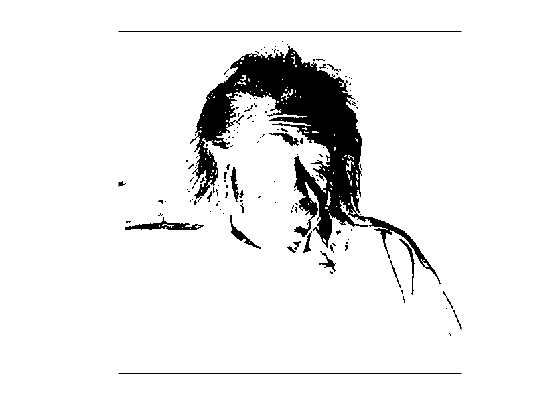

imshow(Ib)

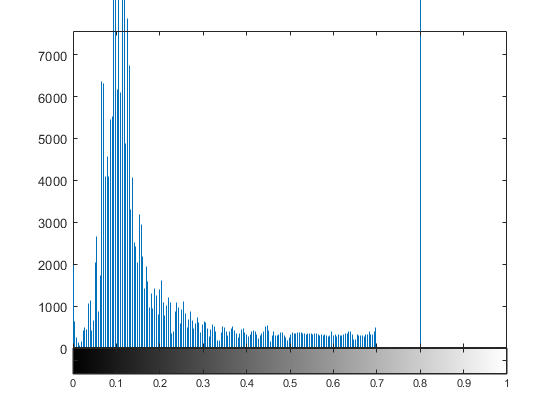

B = 0.8;
Iout = ~Ib*B + Ib.*I2;
imhist(Iout)

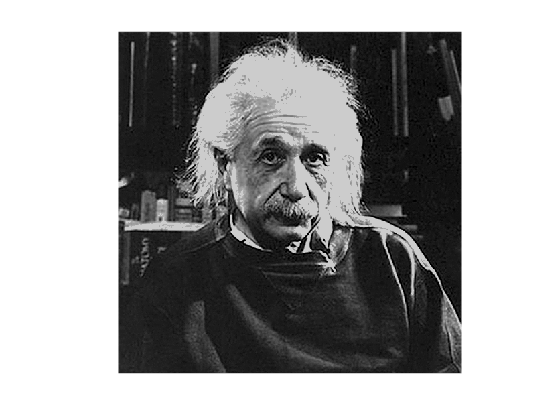

imshow(Iout)

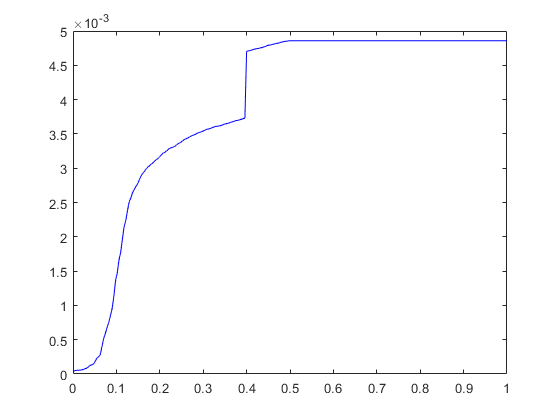

[pixelCounts, grayLevels] = imhist(Iout);
cdf = cumsum(pixelCounts); % Make transfer function (look up table).
cdf = cdf / sum(cdf); % Normalize
plot(grayLevels, cdf, 'b-');



g1=imfilter(g, w); % använder zero-padding och g1 lika stor som g.

Unrecognized function or variable 'w'.

g2=imfilter(g, w, 'symmetric'); %använder symmetric-padding och g2 lika stor som g.

imfilter()